Load the data and visualizing the data

%% Initialization
clear ; close all; clc

load('MNIST.mat');  % variables: Xtrain, yTrain, XTest, 

[numSample,numFeature]=size(XTrain);
whos

  Name               Size                Bytes  Class     Attributes

  XTest           1000x400             3200000  double              
  XTrain          4000x400            12800000  double              
  numFeature         1x1                     8  double              
  numSample          1x1                     8  double              
  yTest           1000x1                  8000  double              
  yTrain          4000x1                 32000  double              



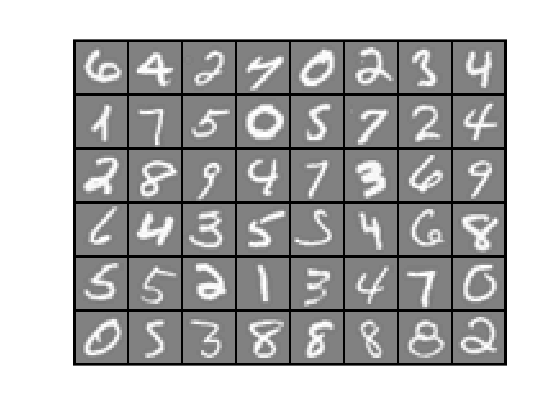


% Randomly select 48 data points to display
rand_indices = randperm(numSample,48);  %returns a row vector containing a random permutation of the integers from 1 to n inclusive.
image_sel = XTrain(rand_indices, :);
displayData(image_sel);  

## 1) Load the weights into variables  w1,w2, and w3

%% add code for loading the weight matrices

load('MNIST_Weight.mat');  % weight matices: w1,w2,w3



## 2) Implement the forward propagation on the traing data

##     - Calculat the training accuracy

%%add code

%1)add code Layer1
% add bias term in the input data
[M, n] = size(XTrain);
bias = ones(M, 1);
X = [bias, XTrain];


%2)add code Layer2
% caculate the linear model in laye2
z2 = X*w1';



%calculate the activation using sigmoid
a2 = sigmoid(z2);


%add bias term
a2 = [ones(size(a2,1),1), a2];





%3)add code Layer3
% caculate the linear model in laye2

z3 = a2*w2';

%calculate the activation using sigmoid
a3 = sigmoid(z3);


%add bias term
a3 = [ones(size(a3,1),1), a3];



%4)add code Layer2
% caculate the linear model in laye2
z4 = a3*w3';


%calculate the activation using sigmoid
a4 = sigmoid(z4);






%5)Find the maximum index among the output nodes
[val, prediction] = max(a4, [],2);



%6) Calculate the Trining accuracy
fprintf('\nTraining Accuracy: %f\n', mean(double(prediction == yTrain)) * 100);


Training Accuracy: 99.875000





%7)Calculate the cost function value with the regularization term ( lamda =1)

m = size(XTrain, 1);

a2 = sigmoid([ones(m, 1) XTrain] * w1');
a3 = sigmoid([ones(m, 1) a2] * w2');
a4 = sigmoid([ones(m, 1) a3] * w3');

lambda = 1;
for L = 1: numFeature
    y= (yTrain == L);
end 

J = (-1/M)*sum(sum(y.*log(a4) + (1-y).*log(1-a4),2));%Cost Function 
J = J +(lambda/(2*M))*(sum(sum(w1(:,2:end).^2,2))+sum(sum(w2(:,2:end).^2,2))+sum(sum(w3(:,2:end).^2,2)));%Reularized Cost Function 
fprintf('\nRegularized Cost Function: %.2f\n', J);


Regularized Cost Function: 5.19


%should be 0.3


% You need to return the following variables correctly 
p = zeros(size(m, 1), 1);

[dummy, p] = max(a4, [], 2);

fprintf('\nTraining Set Accuracy: %f\n', mean(double(p == yTrain)) * 100);


Training Set Accuracy: 99.875000


## 3) Calculate the accuracy on the test data

%%add code

%1)add code Layer1
% add bias term in the input data
X_Test = [ones(size(XTest,1), 1) XTest];


%2)add code Layer2
% caculate the linear model in laye2

z1_Test = X_Test*w1';

%calculate the activation using sigmoid
a2_Test = sigmoid(z1_Test);


%add bias term
a2_Test = [ones(size(a2_Test,1),1) a2_Test];





%3)add code Layer3
% caculate the linear model in laye2
z2_Test = a2_Test*w2';


%calculate the activation using sigmoid
a3_Test = sigmoid(z2_Test);


%add bias term
a3_Test = [ones(size(a3_Test,1),1) a3_Test];



%4)add code Layer2
% caculate the linear model in laye2

z3_Test = a3_Test*w3';


%calculate the activation using sigmoid


a4_Test = sigmoid(z3_Test);




%5)Find the maximum index among the output nodes
[val, Test_prediction] = max(a4_Test, [], 2);



%6) Calculate the Testing accuracy
fprintf('\nTesting Accuracy: %f\n', mean(double(Test_prediction == yTest)) * 100);


Testing Accuracy: 95.200000


## 4) Demo the predcition 

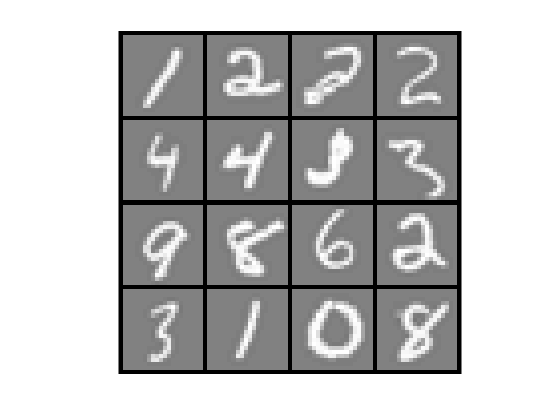

% Add code
% Randomly select 16 test images to display
size = 16;
rand_indices = randperm(numSample,size);  %returns a row vector containing a random permutation of the integers from 1 to n inclusive.






%add code
%Display the selected images
image_sel = XTrain(rand_indices, :);
displayData(image_sel);  






%add code
%dispaly the prediction outputs
a2 = sigmoid([ones(size,1) image_sel]*w1');
a3 = sigmoid([ones(size, 1) a2]*w2');
a4 = sigmoid([ones(size, 1) a3]*w3');

[val, sel_pred] = max(a4, [], 2);

fprintf(['\n The digits are:\n %d %d %d %d \n %d %d %d %d \n %d %d %d %d \n %d %d %d %d \n'], sel_pred);


 The digits are:
 1 2 2 2 
 4 4 3 3 
 9 8 6 2 
 3 1 10 8 
